# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Eth=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Ethaline","VariableNamingRule","preserve")

Visc_Eth = 300×11 table
        DES          Set Type       Condition        Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)        Reference         DES mole fraction
    ___________    ____________    ___________    _____________    __________________    ________________    ______________    _______________    _____________    __________________    _________________

    {'ChCl-EG'}    {'Computed'}    {'Mean'   }    {'DES+Water'}              0                    1              303.15             0.039               39         {'(Celebi, 2019)'}           NaN

Masa_H2O_Eth=Visc_Eth.Mass_percent_Water*100;
Temp_Eth=Visc_Eth.("Temperature(K)");
Mu_Eth=Visc_Eth.("Viscosity(cP)");
data=[Masa_H2O_Eth,Temp_Eth,Mu_Eth];

**2. Eliminación de outliers con función rmoultiers**

length(data)

ans = 300

data_def = rmoutliers(data); length(data_def)

ans = 252

data_median = rmoutliers(data,'median');length(data_median)

ans = 252

data_mean = rmoutliers(data,'mean');length(data_mean)

ans = 294

data_quart = rmoutliers(data,'quartiles');length(data_quart)

ans = 252

data_grubbs = rmoutliers(data,'grubbs');length(data_grubbs)

ans = 286

data_gesd = rmoutliers(data,'gesd');length(data_gesd)

ans = 256

Gráfica de datos de viscosidad con y sin outliers

Masa_H2O_Eth=Visc_Eth.Mass_percent_Water*100;
Temp_Eth=Visc_Eth.("Temperature(K)");
Mu_Eth=Visc_Eth.("Viscosity(cP)");
figure, plot3(Masa_H2O_Eth,Temp_Eth,Mu_Eth,'ob'); hold on
title('Viscosidad Reline + Agua - Datos procesados'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

Gráfica de datos sin outliers mean

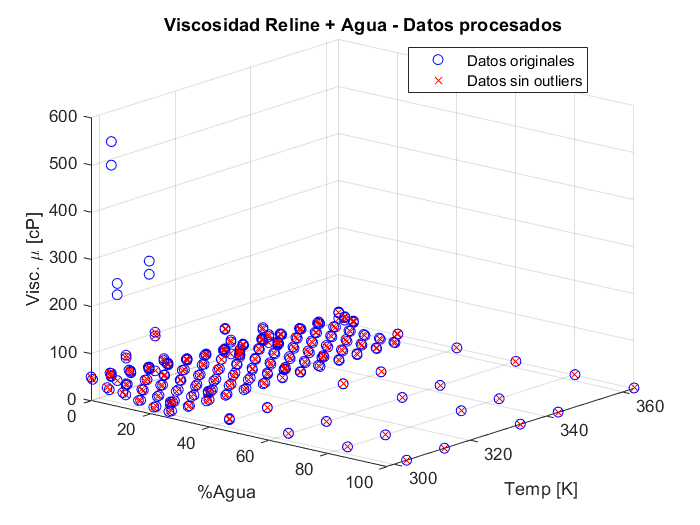

data_mean = rmoutliers(data,'mean');
plot3(data_mean(:,1),data_mean(:,2),data_mean(:,3),'xr')
legend('Datos originales', 'Datos sin outliers',"Location","best")
hold off

**3. División Conjuntos de Datos Entrenamiento y Prueba**

Masa_H2O_Eth=Visc_Eth.Mass_percent_Water*100;
Temp_Eth=Visc_Eth.("Temperature(K)");
Mu_Eth=Visc_Eth.("Viscosity(cP)");
data=[Masa_H2O_Eth,Temp_Eth,Mu_Eth];
data1=rmoutliers(data,'mean');
min(data1(:,3))

ans = 0.2900

max(data1(:,3))

ans = 109

n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 294
       NumTestSets: 1
         TrainSize: 236
          TestSize: 58

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:)

train_data_visc1 =          0  303.1500   39.0000
         0  363.1500    7.7000
         0  333.1500   63.0000
         0  343.1500   39.0000
         0  333.1500   61.0000
         0  363.1500   19.0000
    2.0000  303.1500   32.0000
    2.0000  313.1500   27.0000
    2.0000  333.1500   12.0000
    2.0000  343.1500   10.2000



Masa_H2O_Eth_train=train_data_visc1(:,1);
Temp_Eth_train=train_data_visc1(:,2);
Mu_Eth_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:)

test_data_visc1 =          0  313.1500   30.0000
         0  333.1500   13.0000
         0  343.1500   10.8000
         0  363.1500   21.0000
         0  343.1500   35.0000
    2.0000  363.1500   14.0000
    5.0000  313.1500   57.0000
    5.0000  333.1500   25.0000
    5.0000  343.1500   12.0000
   20.0000  303.1500   12.0000



Masa_H2O_Eth_test=test_data_visc1(:,1);
Temp_Eth_test=test_data_visc1(:,2);
Mu_Eth_test=test_data_visc1(:,3);



**4. Regresión fitlm**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
regre_visc_rel = fitlm(predictores_train,Mu_Eth_train)

regre_visc_rel = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      122.05      13.251     9.2108    1.9477e-17
    x1             -0.30385    0.030161    -10.074    4.7785e-20
    x2             -0.30383    0.040036    -7.5889    7.7037e-13


Number of observations: 236, Error degrees of freedom: 233
Root Mean Squared Error: 12.1
R-squared: 0.413,  Adjusted R-Squared: 0.408
F-statistic vs. constant model: 81.9, p-value = 1.12e-27

Ecuacion

coef1=table2array(regre_visc_rel.Coefficients(1,1));
coef2=table2array(regre_visc_rel.Coefficients(2,1));
coef3=table2array(regre_visc_rel.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 122.0546+(-0.3038)*%Agua+(-0.3038)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Eth_train),max(Masa_H2O_Eth_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Eth_train),max(Temp_Eth_train))

Rango de temperatura: 297.79 K - 363.15 K

**4.1 Regresión toolbox**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
data_train_visc=[predictores_train Mu_Eth_train];
data_train_visc=array2table(data_train_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_train_visc = 236×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

            0                 303.15              39     
            0                 363.15             7.7     
            0                 333.15              63     
            0                 343.15              39     
            0                 333.15              61     
            0                 363.15              19     
            2                 303.15              32     
            2                 313.15              27     
            2                 333.15              12     
            2                 343.15            10.2     
            2                 363.15             6.6     
            2                 313.15             109     
            2                 333.15              41   


predictores_test=[Masa_H2O_Eth_test Temp_Eth_test];
data_test_visc=[predictores_test Mu_Eth_test];
data_test_visc=array2table(data_test_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_test_visc = 58×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

             0                313.15              30     
             0                333.15              13     
             0                343.15            10.8     
             0                363.15              21     
             0                343.15              35     
             2                363.15              14     
             5                313.15              57     
             5                333.15              25     
             5                343.15              12     
            20                303.15              12     
            20                333.15             4.8     
            20                333.15             3.4     
            40                313.15             2.6     

[regre_visc_rel, validationRMSE] = MediumGaussianSVM_Visc_Ethaline(data_train_visc)

regre_visc_rel = struct with fields:
           predictFcn: @(x)svmPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Mass_percent_Water'  'Temperature(K)'}
        RegressionSVM: [1×1 RegressionSVM]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 10.5756

regre_visc_rel.RegressionSVM

ans =   RegressionSVM
           PredictorNames: {'Mass_percent_Water'  'Temperature(K)'}
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [159×1 double]
                     Bias: 9.7097
         KernelParameters: [1×1 struct]
                       Mu: [21.8282 330.4936]
                    Sigma: [26.1302 19.6851]
          NumObservations: 236
           BoxConstraints: [236×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [236×1 logical]
                   Solver: 'SMO'


  Properties, Methods


regre_visc_rel.HowToPredict

ans =     'To make predictions on a new table, T, use: 
       yfit = c.predictFcn(T) 
     replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. 
      
     The table, T, must contain the variables returned by: 
       c.RequiredVariables 
     Variable formats (e.g. matrix/vector, datatype) must match the original training data. 
     Additional variables are ignored. 
      
     For more information, see How to predict using an exported model.'
